clear,clc;

## Measured

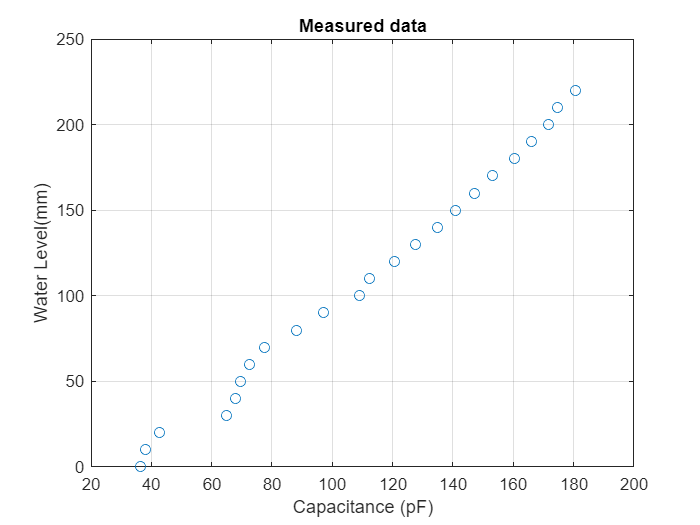

WaterLevel = 0:10:220;
Capacitance = [36.56, 38.22, 42.64, 64.90, 67.77, 69.45, 72.62, 77.58, 88.19, 97.12, 108.90, 112.39, 120.72, 127.44, 134.84, 140.81, 147.28, 153.07, 160.54, 165.88, 171.53, 174.48, 180.66];

plot(Capacitance,WaterLevel,'o','DisplayName','raw data')
title("Measured data")
ylabel("Water Level(mm)")
xlabel("Capacitance (pF)")
grid on

## Curve Fitting

x = Capacitance';
y = WaterLevel';

x_train = x(1:2:end)

x_train =    36.5600
   42.6400
   67.7700
   72.6200
   88.1900
  108.9000
  120.7200
  134.8400
  147.2800
  160.5400


y_train = y(1:2:end);
n_train = length(x_train);

x_test = x(2:2:end);
y_test = y(2:2:end);
n_test = length(x_test);

X = [ones(n_train,1) , x_train]; %Line
XT = X';
Y = y_train;

% Least-Square Coefficient Estimates
A = ((XT*X)^(-1))*(XT*Y)

A =   -50.9855
    1.4500


## Training and test errors

Yc = X * A

Yc =     2.0283
   10.8445
   47.2842
   54.3170
   76.8942
  106.9247
  124.0643
  144.5389
  162.5775
  181.8051


RSS_train = sum((Y-Yc).^2);
X_test = [ones(n_test,1) , x_test];
Y_test = y_test;
Yc_test = X_test * A

Yc_test =     4.4353
   43.1226
   49.7203
   61.5092
   89.8431
  111.9854
  133.8086
  153.1957
  170.9733
  189.5484


RSS_test = sum((Y_test-Yc_test).^2);

MSE_train = RSS_train/n_train

MSE_train = 30.3645

MSE_test = RSS_test/n_test

MSE_test = 33.5341

## 95% confidence interval 

c = 0.95;   % confidence interval 
alpha = 1- c;
m = 1;      % number of independant variable ( x1 = x)
v = n_train - ( m + 1)

v = 10

t_a2 = tinv(1-alpha/2 , v)

t_a2 = 2.2281

Syx = sqrt(RSS_train/v)

Syx = 6.0363


uncertainty = t_a2 * (Syx/sqrt(n_train));

Y_ub = Yc + uncertainty;
Y_lb = Yc - uncertainty;
uncertainty

uncertainty = 3.8826

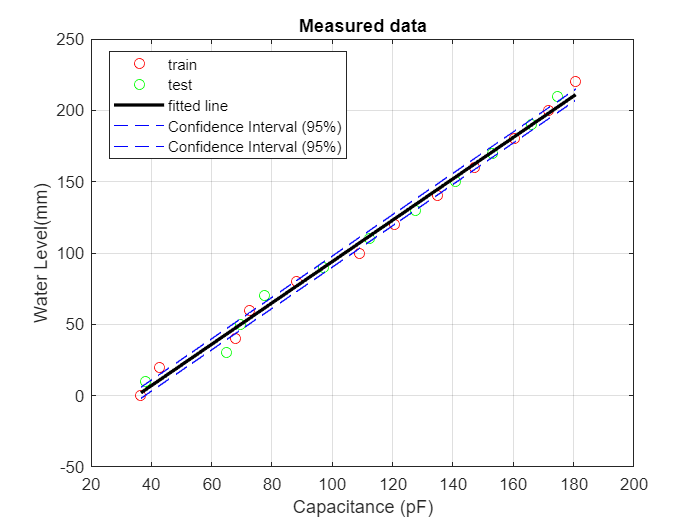

plot(x_train,y_train,'ro','DisplayName','train');
hold on; 
plot(x_test,y_test,'go','DisplayName','test');
hold on; 
plot(x_train,Yc,'k','LineWidth', 2 , 'DisplayName','fitted line');
hold on
plot(x_train,[Y_lb,Y_ub],'--b' , 'DisplayName','Confidence Interval (95%)');
grid on
title("Measured data")
ylabel("Water Level(mm)")
xlabel("Capacitance (pF)")
set(legend,...
    'Position',[0.155595232168833 0.697460312919011 0.339642863069262 0.204761909303211]);
hold off

## Simulation

Capacitance_sim = [18.95177284, 57.54839048, 95.21385846, 133.2374467, 170.9116977, 209.127877, 246.5552793, 284.8417479, 322.5471845, 360.173357, 398.2421676];
WaterLevel_sim = 0:30:300;
Capacitance_cal  = (WaterLevel_sim - A(1))/A(2)

Capacitance_cal =    35.1612   55.8502   76.5392   97.2282  117.9172  138.6061  159.2951  179.9841  200.6731  221.3620  242.0510


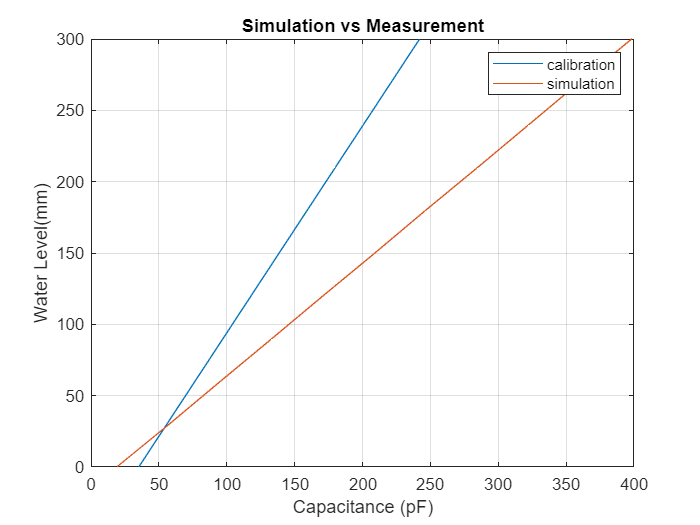


plot(Capacitance_cal,WaterLevel_sim,'DisplayName','calibration')
grid on 
hold on
plot(Capacitance_sim,WaterLevel_sim,'DisplayName','simulation')
hold on
legend
ylabel("Water Level(mm)")
xlabel("Capacitance (pF)")
title("Simulation vs Measurement")

## Theory

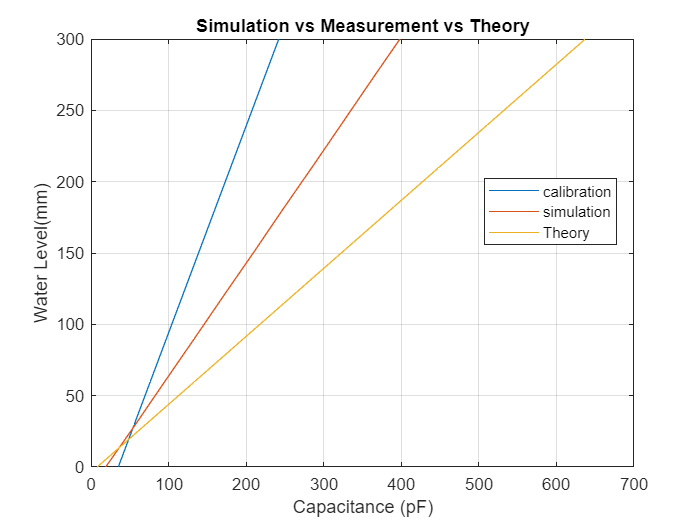

E0 = 8.85 * 10^(-12);
Ew = 80;
Ea = 1.0006;
W = 30 * 10^(-3);
d = 10 * 10^(-3);
Hw_max = 300 * 10^(-3);

Capacitance_the = E0*(W*Hw_max)/d + E0*(W*(WaterLevel_sim* 10^(-3))/d)*(Ew-1);
Capacitance_the = Capacitance_the*10^12;
plot(Capacitance_the, WaterLevel_sim,'DisplayName','Theory')
title("Simulation vs Measurement vs Theory")
legend
set(legend,'Position',[0.691309521459398 0.5341269814022 0.189642859492983 0.12619047891526]);
hold off

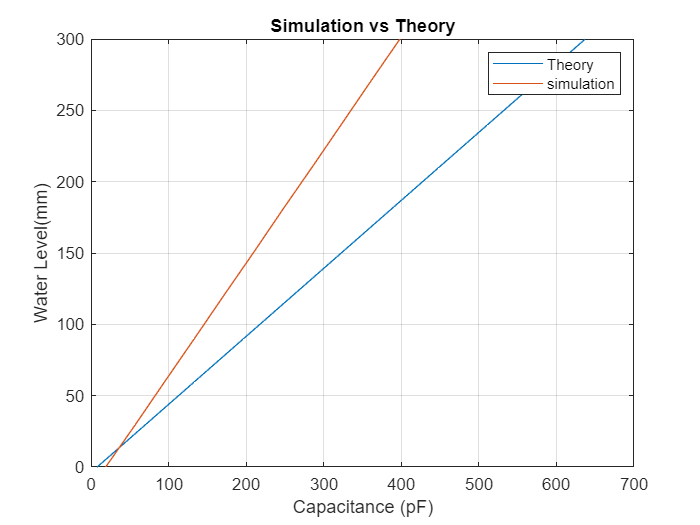

plot(Capacitance_the, WaterLevel_sim,'DisplayName','Theory')
grid on 
hold on
plot(Capacitance_sim,WaterLevel_sim,'DisplayName','simulation')
title("Simulation vs Theory")
ylabel("Water Level(mm)")
xlabel("Capacitance (pF)")
legend